# Creación de los brazos y Articulaciones de un Robot

# Método de Denavit–Hartenberg (D-H)

Dificultad: Alta (Teoría)

## Tipos de ejes de un robot: 

- **Rotacionales**: Un brazo gira respecto del brazo anterior en un nodo.

- **Prismáticos**: Un brazo se desplaza respecto al brazo anterior

- **Fijos**: No se mueven, pero son útiles para definir puntos en el espacion (TCP).

#### Robot industriales antropomórficos:

- Simulan un brazo humano, con antebrazo, brazo y muñeca.

- Suelen tener $6$ grados de libertad, normalmente, $6$ ejes rotacionales.

#### Ejes de un robot

- **Eje base**: Define la referencia de la base del robot.

- **Ejes de los nodos**: Definen la posición de cada nodo. 

- **Eje **$z$** del nodo**: Debe define el giro o traslación del nodo (variable).

- **Punto de trabajo (TCP)**: Eje del último nodo, o de la herramienta si la tiene.

- **Codos**: Ejes $[1,4,6]$, definen la posición del antebrazo, brazo y muñeca. Puede haber $8$ formas de ir a un punto.

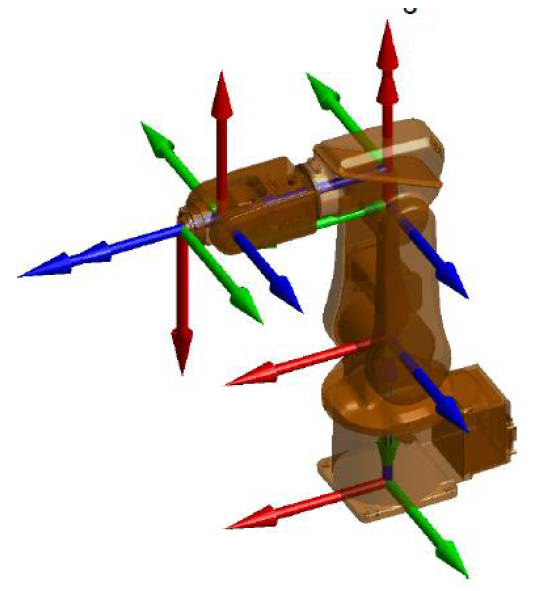

## Método Denavit–Hartenberg (D-H) 

Obtener los ejes de los nodos: De un eje $n-1$ al siguiente eje $n$,

- Rotar en $z$ ($\theta_z$) (Variable+ Fija)

- Trasladar en $z$ ( $d$) (Fija)

- Trasladar en $x$ ($a$) (Fija)

- Rotar en $x$ ($\alpha$) (Fija)


$$^{n-1}T_n(R_{z_n})= T(R_{z_n})*T(t_{z_n})*T(t_{x_n})*T(R_{x_n})$$


Sin embargo hay variaciones. De hecho en *Robotic Toolbox* no se cumple la norma.

## Ejemplo del método de D-H

- Robot irb120,

- Se calcula la matriz homogénea entre el eje anterior y el actual. Se dibuja un palo entre ambos ejes.

- La posición de cada eje depende de la estructura del robot (matriz DH fija) y la rotación de los ejes.

- El TCP (*Point Center Tool*) del robot es el último eje o la herramienta si la hay. 

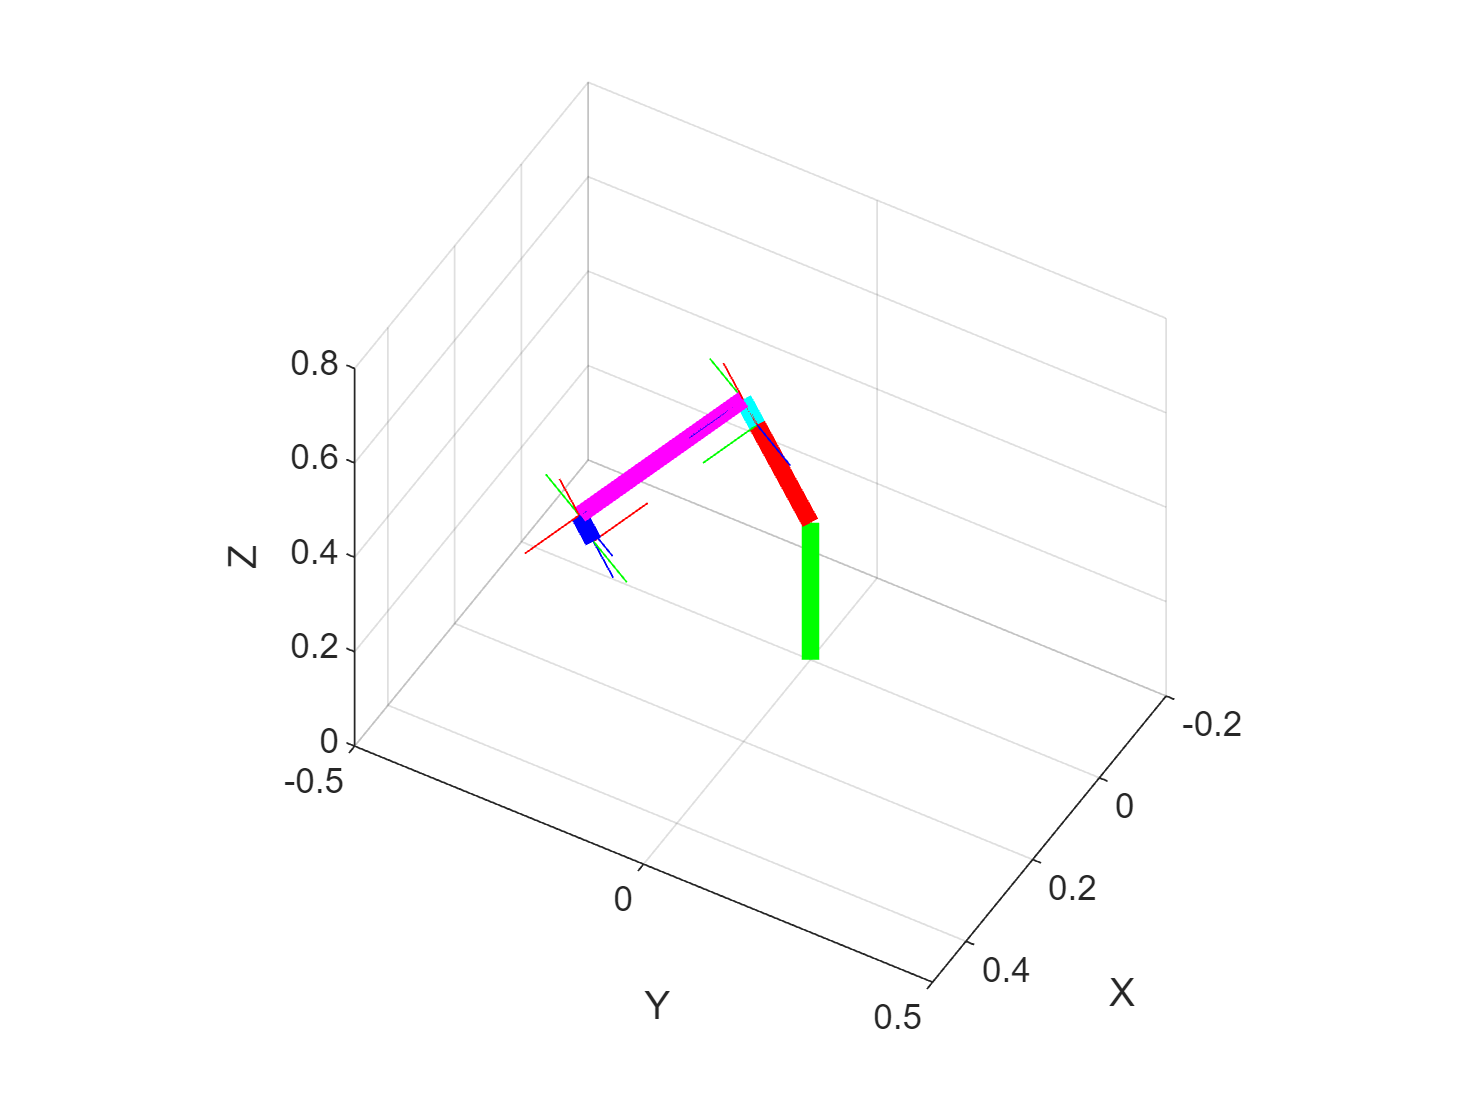

H = se3
   -0.8138    0.5000   -0.2962    0.3251
    0.4698    0.8660    0.1710   -0.1877
    0.3420    0.0000   -0.9397    0.4385
         0         0         0    1.0000


deg= pi/180;
theta = [0,    -90,    0,   0,      0,    180]'*deg;
d =     [0.290,  0,    0,   0.302,  0,  0.072]';
a =     [0,    0.270, 0.07, 0,      0,      0]';
alpha = [-90,    0,   -90,  90,    -90,     0]'*deg;

DHm= [theta, d, a, alpha];
%axis([-0.2, 0.5, -0.5, 0.5, 0, 0.8]*1e3)

n= 6;
joint= [-30,20,0,0,90,0]*deg;

figure
for j= 1:size(joint,1)
    H= plotDH(DHm, joint(j,:))
    axis([-0.2, 0.5, -0.5, 0.5, 0, 0.8]);
    view(120,45);
    pause(1)
end

## Herramienta objeto *RigidBody*

- El objeto *RigidBody* está definido en la librería Robotic Toolbox para analizar y obtener gráficas de un robot.

- Es una herramienta potente pero difícil de manejar de forma manual.

- La método de DH que emplea no es el estándar, por lo que hemos usado las matrices homogéneas de cada eje de forma directa.

- La función $setFixedTransform()$ modifica el brazo desde objeto padre a la articulación, H= $robot.Bodies\{i\}.Joint.JointToParentTransform$. 

- El movimiento variable en $\theta_z$ se produce en la articulación padre, y en ésta se modifica el brazo del robot

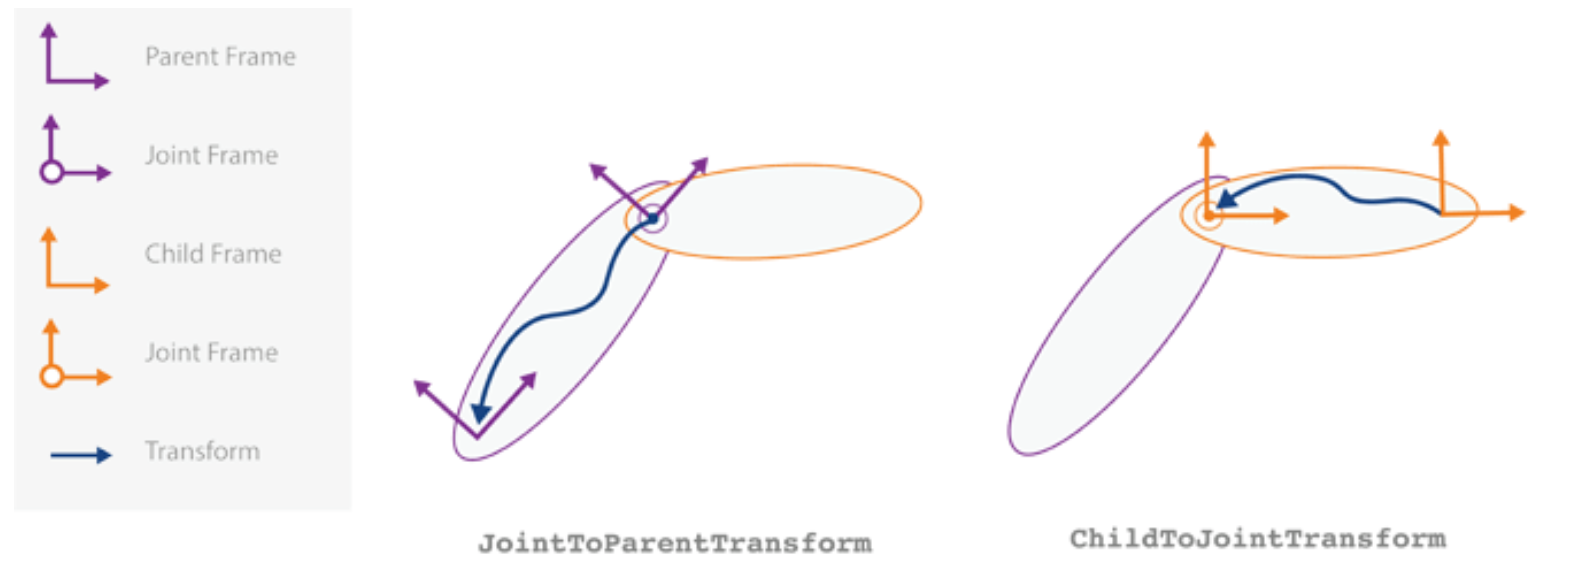

- La posición de la primera articulación es la posición respecto a la base del robot, por defecto, cero.

- Hay una $7^o$ articulación fija, que marca el TCP del robot.

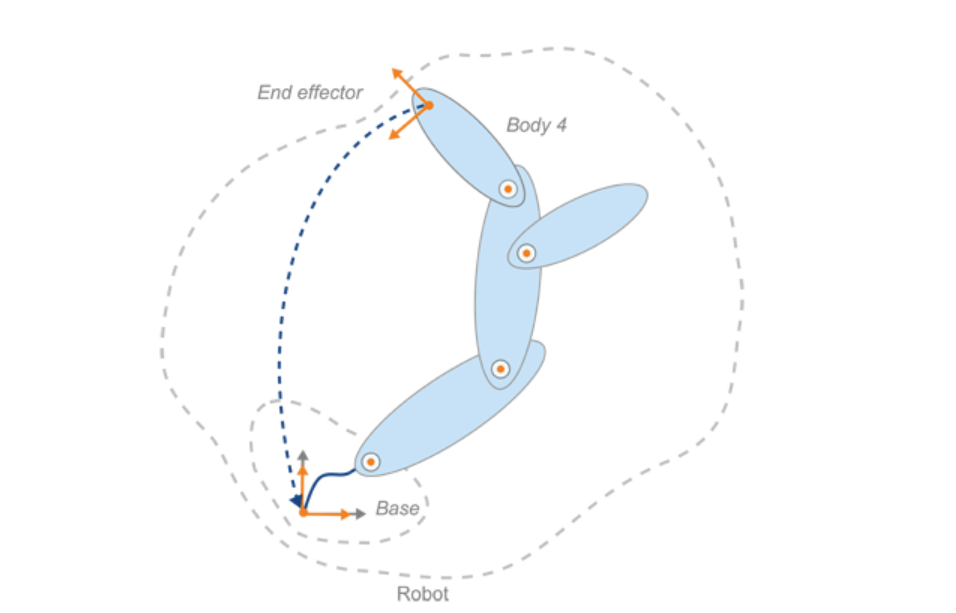

- Si se aplica el método DH en RigidBody, utiliza el movimiento fijo $[a,\alpha_x,d,\theta_z]$ y la rotación variable $\theta_z$ la realiza la articulación hijo. La matriz convencional DH no es válida para este movimiento.

deg= pi/180;
theta = [0,    -90,    0,   0,      0,    180]'*deg;
d =     [0.290,  0,    0,   0.302,  0,  0.072]';
a =     [0,    0.270, 0.07, 0,      0,      0]';
alpha = [-90,    0,   -90,  90,    -90,     0]'*deg;

DHm= [theta,d,a,alpha];

robot= RobotDH(DHm)

robot =   rigidBodyTree with properties:

     NumBodies: 7
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'Body1'  'Body2'  'Body3'  'Body4'  'Body5'  'Body6'  'Body7'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'column'


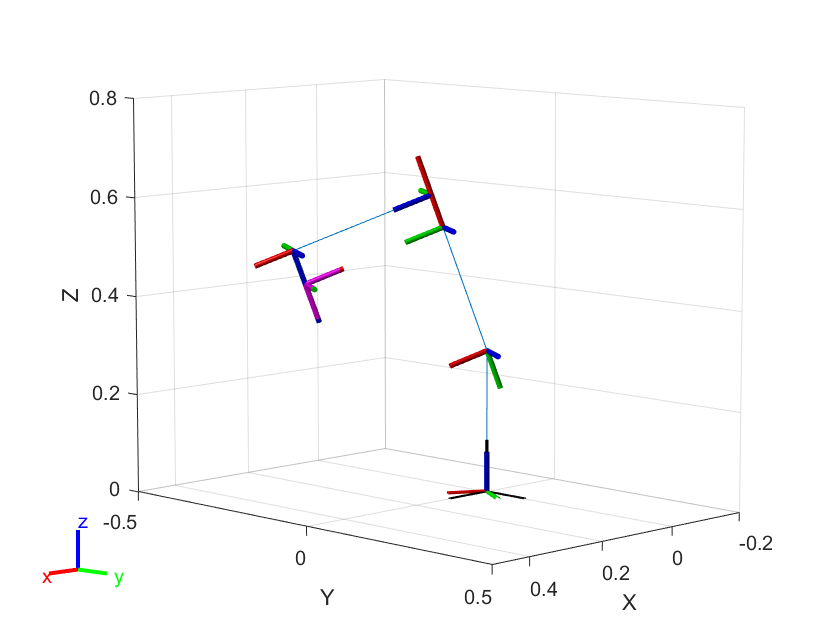

figure
q= [-30,20,0,0,90,0]'*deg;
show(robot, q);
axis([-0.2, 0.5, -0.5, 0.5, 0, 0.8])

% Obtener la matriz homogénea del TCP
H= getTransform(robot, [-30,20,0,0,90,0]'*deg, 'Body7')

H =    -0.8138    0.5000   -0.2962    0.3251
    0.4698    0.8660    0.1710   -0.1877
    0.3420    0.0000   -0.9397    0.4385
         0         0         0    1.0000


### Gráficas *.stl de los brazos del robot

- Puede incorporar gráficas *.slt de cada brazo, en formato binario.

- Se debe mover la gráfica a su posición correspondiente, normalmente la articulación padre de la siguiente *body*.

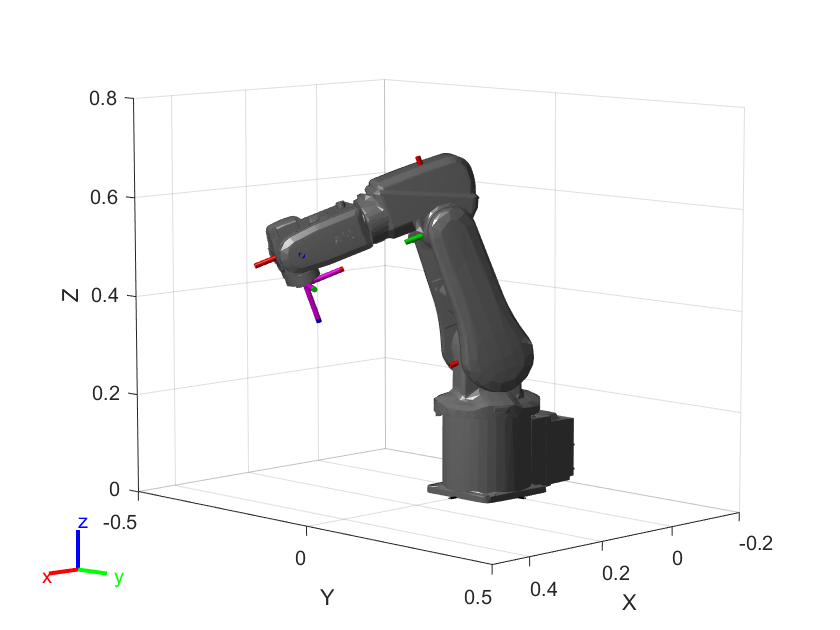

addVisual(robot.Base,"Mesh",'Robots/irb120DH/link0_bin.stl')
for i= 1:6
    cad= sprintf('Robots/irb120DH/link%d_bin.stl',i);
    H= robot.Bodies{i+1}.Joint.JointToParentTransform;
    addVisual(robot.Bodies{i},"Mesh", cad, H)
end

figure
q= [-30,20,0,0,90,0]'*deg;
show(robot, q);
axis([-0.2, 0.5, -0.5, 0.5, 0, 0.8])

[**ARTE: A ROBOTICS TOOLBOX FOR EDUCATION**](http://arvc.umh.es/arte/index.html)

- Es una librería de robótica realizada con Matlab ([robotics-Toolbox (Corke)](https://petercorke.com/toolboxes/robotics-toolbox/)) que dispone de muchos modelos de robots industriales definidos en formato D-H.

- Los mismos podrían ser convertidos a formato RigidBody de forma simular a la expuesta.

## Funciones locales para la creación de un robot

## De forma manual

function Ht= plotDH(DHm, joint)

   if nargin==0
       error('Ht= plotDH(DHm, joint)')
   elseif nargin==1 
      joint=[];
   end
   if isempty(joint)
      joint= zeros(1,6);
   end

   Ht= se3;
   col= {'b','g','r','c','m','y'};
  % figure
   hold off
   %axis([-0.2, 0.5, -0.5, 0.5, 0, 0.8]*1e3)
   %hold on
   for i= 1:size(DHm,1)
      eje0= trvec(Ht);
      H= se3([DHm(i,1)+joint(i),0,0],'eul')*se3([0,0,DHm(i,2)],'trvec')*...
         se3([DHm(i,3),0,0],"trvec")*se3([0,0,DHm(i,4)],'eul');
      Ht= Ht*H;
      eje= trvec(Ht);
      plotTransforms(Ht, 'FrameSize', 0.1, 'AxisLabels', 'on');
      plot3([eje0(1), eje(1)], [eje0(2), eje(2)], [eje0(3), eje(3)], ...
                    'Color',  col{rem(i,6)+1} ,'LineWidth', 5 );
      hold on;
   end
end


## Usando los objetos RigidBody


function robot= RobotDH(DHm)

   dim= size(DHm,1);
   robot = rigidBodyTree;
   body = rigidBody('Body1');
   jnt = rigidBodyJoint('jnt1','revolute');
   setFixedTransform(jnt,eye(4));
   body.Joint = jnt;
   addBody(robot,body,'base')

   for i= 2:dim+1
      if i<=dim
         body = rigidBody(sprintf('Body%d',i));
         jnt = rigidBodyJoint(sprintf('jnt%d',i),'revolute');
      else
          body = rigidBody(sprintf('Body%d',i));
          jnt = rigidBodyJoint(sprintf('jnt%d',i),'fixed');
       end
%      setFixedTransform(jnt, DHm(i,:),'dh');
      H= tform(se3([DHm(i-1,1),0,0],'eul')*se3([0,0,DHm(i-1,2)],'trvec')*...
         se3([DHm(i-1,3),0,0],'trvec')*se3([0,0,DHm(i-1,4)],'eul'));
      % H respecto del padre
      setFixedTransform(jnt, H);
      body.Joint = jnt;
      addBody(robot,body,sprintf('Body%d',i-1));
   end

   robot.DataFormat= 'column';
end


## Funciones de creación

% Robot Manipulators
%     rigidBodyJoint                 - Create a joint
%     rigidBody                      - Create a rigid body
%     rigidBodyTree                  - Create a tree-structured robot
%     addBody
%     removeBody 
%     replaceBody
%     setFixedTransform


## Funciones avanzadas de manipulación RigidBody


%     interactiveRigidBodyTree       - Interact with rigid body tree robot models
%     capsuleApproximation           - Capsule approximation of robot collision geometries
%     importrobot                    - Import rigid body tree model from URDF file, text, or Simscape Multibody model
%     loadrobot                      - Load robot model as rigidBodyTree
%     jointSpaceMotionModel          - Model rigid body tree motion given joint-space inputs
%     taskSpaceMotionModel           - Model rigid body tree motion given task-space reference inputs
%     manipulatorRRT                 - Plan motion for rigid body tree using bidirecitonal RRT
%     manipulatorCHOMP               - CHOMP for rigid body tree
%     manipulatorStateSpace          - State space of a rigid body tree
%     manipulatorCollisionBodyValidator - Validate a state of a rigid body tree against a cell-array of convex collision bodies
%     workspaceGoalRegion            - Define a workspace region of end-effector goal poses
%     chompCollisionOptions          - Collision options for CHOMP trajectories
%     chompSmoothnessOptions         - Smoothness options for CHOMP trajectories
%     chompSolverOptions             - Solver options for CHOMP
 